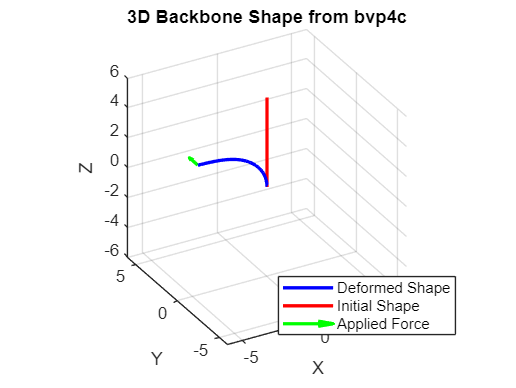

%This is a test file for beam bending simulation

clear, close all


%Ok now trying 3D with same numbers

% Parameters
EI = 0.7;         % Bending stiffness
GJ = .7;
r = 5 / pi;        % Robot radius
n = 1;             % Number of segments
N = 1000;         % Number of discretization points
% Initial actuator positions
act_11_start = [r; 0; 0; 1];
act_12_start = [r*cos(2*pi/3); r*sin(2*pi/3); 0; 1];
act_13_start = [r*cos(4*pi/3); r*sin(4*pi/3); 0; 1];
Base_coord = eye(4);


% Generate curvature and segment info
[T, act1, act2, act3, curvature, Lck, beta, theta] = ...
    gen_transform_2(6, 6, 6, r, act_11_start, act_12_start, act_13_start, Base_coord);

%Force applied at tip, N
Fx = 0.0; 
Fy = 0.02; 
Fz = 0.0;

s_vals = linspace(0, Lck, N);

% Angle functions representing intrinsic curvature (constant curvature)
theta_init = theta * ones(size(s_vals));               % Constant bending direction
%phi_init = (pi/2) - beta * s_vals / Lck;
beta_init = beta * s_vals / Lck;      
% Initialize position array
p_init = zeros(3, N);

% Integrate tangent vector to get position
for i = 2:N
    ds = s_vals(i) - s_vals(i-1);
    th = theta_init(i-1);
    bt = beta_init(i-1);

    tangent = [sin(bt)*cos(th);
               sin(bt)*sin(th);
               cos(bt)];
    p_init(:, i) = p_init(:, i-1) + tangent * ds;
end


% Interpolate intrinsic curvature angles for continuous evaluation
theta_init_interp = @(sq) interp1(s_vals, theta_init, sq);
%phi_init_interp = @(sq) interp1(s_vals, phi_init, sq);
beta_interp  = @(sq) interp1(s_vals, beta_init,  sq);

% Initial guess for deviations: zero everywhere
%init_guess = @(s) zeros(4, numel(s));
init_guess = @(s) [
    1e-2*s;                   % θ(s): no twist initially
    0*s;           % φ(s): linear bending from vertical
    0*s;                   % θ'(s): no twist rate
    0*s;   % φ'(s): constant curvature (bending rate)
];
% Define ODE function for deviations [dtheta; dphi; dtheta'; dphi']
% State vector y = [dtheta; dphi; dtheta_s; dphi_s]
% ODE function for deviation variables y = [dtheta; dphi; dtheta'; dphi']
odefun = @(s, y) eul_fun_3D(s, y, EI, GJ,Fx, Fy, Fz,theta_init_interp,beta_interp);
function dy = eul_fun_3D(s, y, EI, GJ,Fx, Fy, Fz,theta_interp,beta_interp)
    % y = [theta; beta; dtheta/ds; dbeta/ds]
    % y = [theta; beta; dtheta/ds; dbeta/ds]
    % theta: twist angle (radians)
    % beta: bending curvature angle (radians)
    % omega = dtheta/ds (twist curvature)
    % nu = dbeta/ds (bending curvature)
    %
    % EI: bending stiffness
    % GJ: torsional stiffness
    % Fx, Fy, Fz: external force components (global frame)
    % torque: external torque about rod axis (scalar)
    % theta_interp(s), beta_interp(s): intrinsic curvature angles (functions)
    % L_moment: effective moment arm length for bending moment
    L_moment = 3;
    torque = 0;
    % Add intrinsic curvature to current state angles
    theta = theta_interp(s) + y(1);
    beta  = beta_interp(s) + y(2);
    omega = y(3);
    nu    = y(4);

    % Tangent vector (rod axis)
    t = [sin(beta)*cos(theta);
         sin(beta)*sin(theta);
         cos(beta)];

    % Global force vector
    Fg = [Fx; Fy; Fz];

    % Component of force perpendicular to tangent (causes bending)
    F_perp = Fg - (Fg'*t)*t;

    % Select reference vector for local frame (avoid singularity)
    if abs(dot(t, [0;0;1])) > 0.99
        ref = [1;0;0];
    else
        ref = [0;0;1];
    end
    
    % Local bending axis (y axis)
    y_axis = cross(t, ref);
    y_axis = y_axis / norm(y_axis);

    % Signed bending moment from perpendicular force projected onto bending axis
    M_b = L_moment * dot(F_perp, y_axis);

    % Torsional moment is provided externally
    M_t = torque;

    % Build derivatives vector
    dy = zeros(4,1);
    dy(1) = omega;       % dtheta/ds (twist rate)
    dy(2) = nu;          % dbeta/ds (bending rate)
    dy(3) = M_t / GJ;    % d²theta/ds² (twist acceleration)
    dy(4) = M_b / EI;    % d²beta/ds² (bending acceleration)
end

% Boundary conditions for deviations: no change at base, zero slope at tip
bcfun = @(ya, yb) [
    ya(1);  % dtheta(0) = 0 (no deviation at base)
    ya(2);  % dphi(0) = 0
    yb(3);  % dtheta'(L) = 0 (free end)
    yb(4);  % dphi'(L) = 0
];



% Setup initial mesh for bvp4c
solinit = bvpinit(linspace(0, Lck, N), init_guess);

% Solve BVP
options = bvpset('RelTol',1e-5,'AbsTol',1e-7);
sol = bvp4c(odefun, bcfun, solinit, options);

% Extract solution
s_sol = linspace(0, Lck, N);
y_sol = deval(sol, s_sol);

% Compute total angles by adding deviations to intrinsic angles
theta_tot = theta_init_interp(s_sol) + y_sol(1,:);
%phi_tot = phi_init_interp(s_sol) + y_sol(2,:);
beta_tot  = beta_interp(s_sol)  + y_sol(2, :);

%% STEP 3: INTEGRATE TO GET DEFORMED SHAPE
p_def = zeros(3, N);
for i = 2:N
    ds = s_sol(i) - s_sol(i-1);
    th = theta_tot(i-1);
    bt = beta_tot(i-1);

    tangent = [sin(bt)*cos(th);
               sin(bt)*sin(th);
               cos(bt)];
    p_def(:, i) = p_def(:, i-1) + tangent * ds;
end

figure
% Plot deformed shape
plot3(p_def(1,:), p_def(2,:), p_def(3,:), 'b-', 'LineWidth', 2);
hold on;

% Plot initial curved shape
plot3(p_init(1,:), p_init(2,:), p_init(3,:), 'r-', 'LineWidth', 2);

title('Initial (Zero-Force) Curved Shape');


% Applied force arrow
quiver3(p_def(1,end), p_def(2,end), p_def(3,end), Fx/sqrt(Fx^2+Fy^2+Fz^2), Fy/sqrt(Fx^2+Fy^2+Fz^2), Fz/sqrt(Fx^2+Fy^2+Fz^2), ...
    'Color', 'green', 'LineWidth', 2, 'AutoScaleFactor', 1, 'MaxHeadSize', 10);

xlabel('X'); ylabel('Y'); zlabel('Z');
grid on; axis equal;
xlim([-6 6])
ylim([-6 6])
zlim([-6 6])
title('3D Backbone Shape from bvp4c');
legend('Deformed Shape','Initial Shape',  'Applied Force', 'Location', 'best');




hold off

Functions


function dy = eul_fun(x,y,EI,R,Fx,Fy)
    dy = zeros(1,2);
    dy(1) = y(2);
    dy(2) = 1/EI*(-Fx*cos(y(1))+Fy*sin(y(1)));
 end



function [T_k, act_1_end, act_2_end, act_3_end, rho_k,L_ck,beta_k,theta_k] = ...
    gen_transform_2(L_k1, L_k2, L_k3, r, act_1_start, act_2_start, act_3_start, T_prev)

    phi_kj = 0; % fixed angle

    % calculate length
    L_ck = (L_k1 + L_k2 + L_k3)/3;
    beta_k = 2*sqrt(L_k1^2 + L_k2^2 + L_k3^2 - L_k1*L_k2 - L_k1*L_k3 - L_k2*L_k3)/(3*r);
    theta_k = atan2(3*(L_k2 - L_k3), sqrt(3)*(L_k2 + L_k3 - 2*L_k1));

    rho_k = beta_k/L_ck; % Curvature calc

    % Rotation matrix
    ct = cos(theta_k);
    st = sin(theta_k);
    cb = cos(beta_k);
    sb = sin(beta_k);

    R_k = [
        cb*ct^2 + st^2,      (cb-1)*ct*st,       ct*sb;
        (cb-1)*ct*st,        ct^2 + cb*st^2,     st*sb;
        -ct*sb,              -st*sb,             cb
    ];

    % Position vector
    P_k = (1/rho_k) * [(1-cb)*ct; (1-cb)*st; sb];

    % Transformation matrix
    T_k = [R_k P_k; 0 0 0 1];
    if abs(rho_k) < 1e-6
        T_k = [1 0 0 0
               0 1 0 0
               0 0 1 L_ck
               0 0 0 1];
    end
    % actuator end point calculation
    act_1_end = T_prev*T_k*act_1_start;
    act_2_end = T_prev*T_k*act_2_start;
    act_3_end = T_prev*T_k*act_3_start;
end